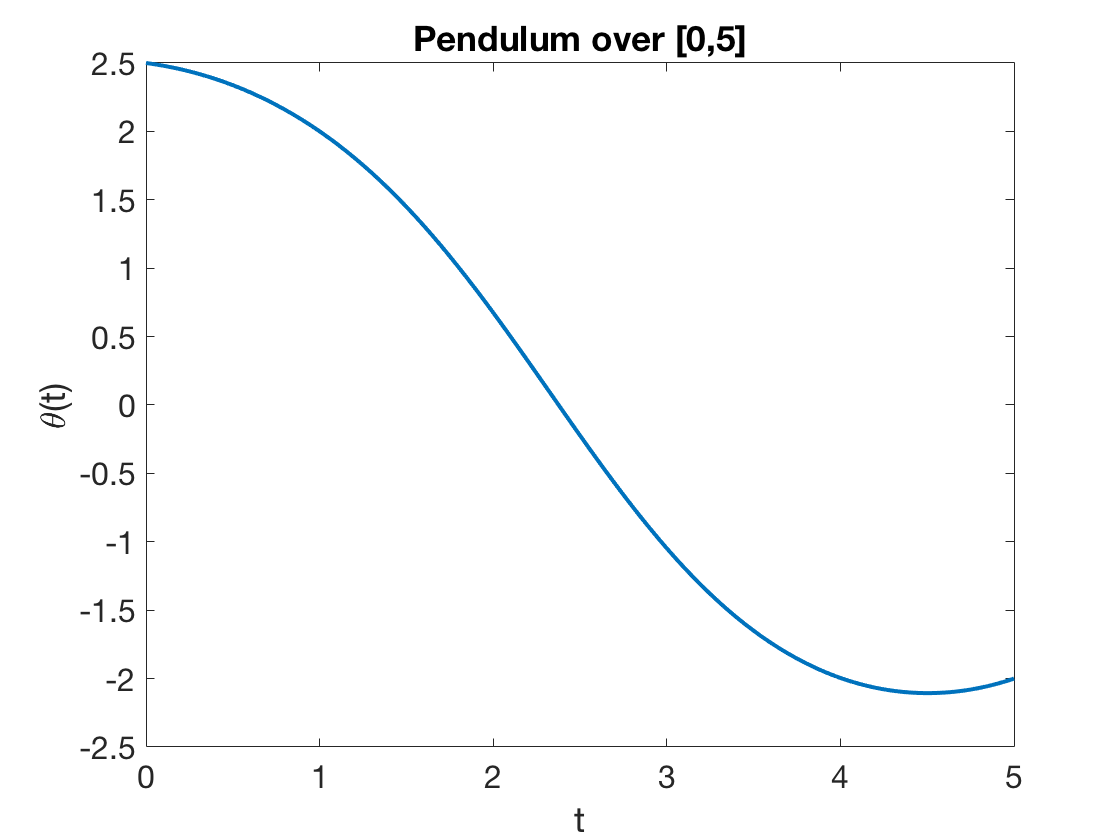

phi = @(t,theta,omega) -0.05*omega - sin(theta);
init = linspace(2.5,-2,101)';
[t,theta] = bvp(phi,[0,5],2.5,[],-2,[],init);
plot(t,theta)
xlabel('t'), ylabel('\theta(t)')   % ignore this line
title('Pendulum over [0,5]')   % ignore this line

Note how the angle decreases throughout the motion until near the end. If we extend the time interval longer, then we find a rather different solution.

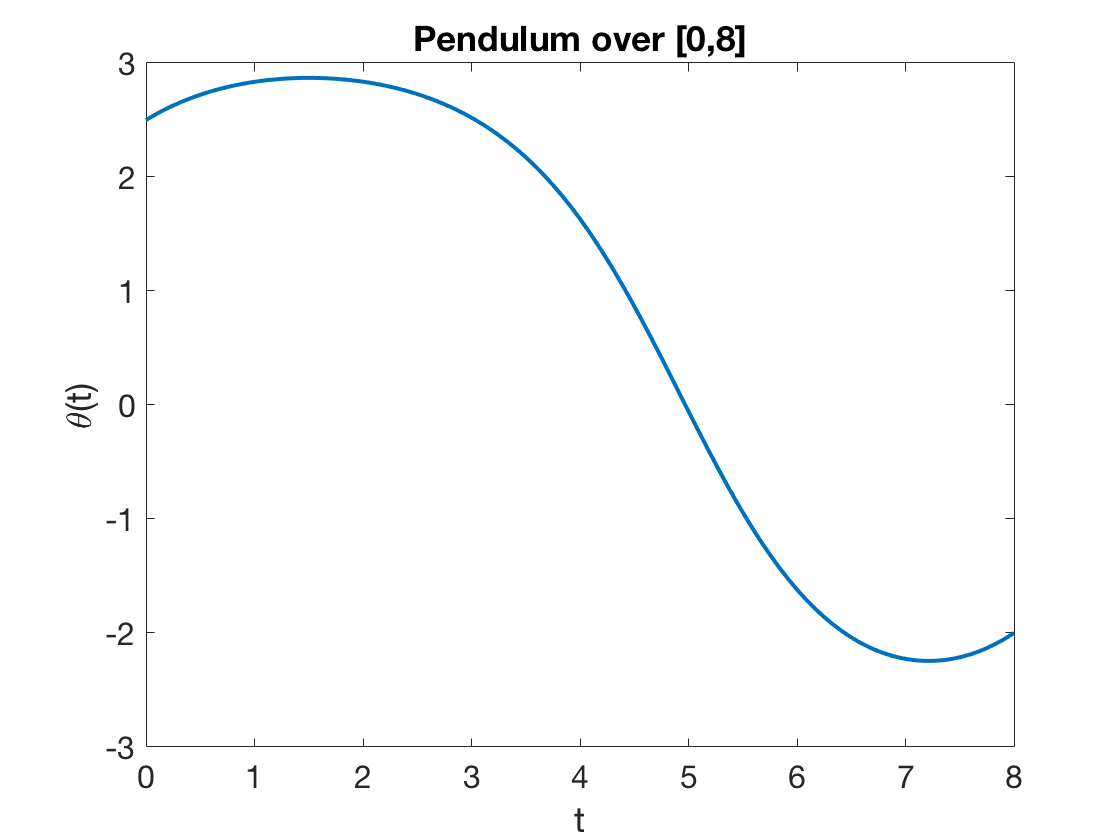

[t,theta] = bvp(phi,[0,8],2.5,[],-2,[],init);
plot(t,theta)
xlabel('t'), ylabel('\theta(t)')   % ignore this line
title('Pendulum over [0,8]')   % ignore this line

This time the angle initially *increases*, and the pendulum hovers near the vertical position before swinging back down. 